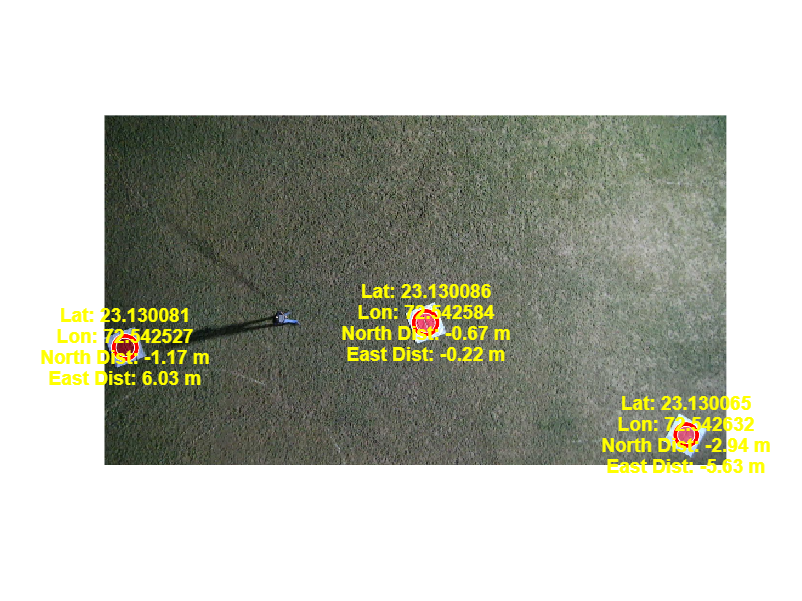

lat = 23.13009173276929;
lon = 72.54258162679749;
head = 0;
high = 15;

image = imread("/MATLAB Drive/WhatsApp Image 2024-10-29 at 9.22.58 PM.jpeg");

hsv = rgb2hsv(image);

lower_red1 = [0, 0.39, 0.39];
upper_red1 = [0.055, 1, 1];
lower_red2 = [0.94, 0.39, 0.39];
upper_red2 = [1, 1, 1];

mask1 = (hsv(:,:,1) >= lower_red1(1) & hsv(:,:,1) <= upper_red1(1)) & ...
        (hsv(:,:,2) >= lower_red1(2) & hsv(:,:,2) <= upper_red1(2)) & ...
        (hsv(:,:,3) >= lower_red1(3) & hsv(:,:,3) <= upper_red1(3));
         
mask2 = (hsv(:,:,1) >= lower_red2(1) & hsv(:,:,1) <= upper_red2(1)) & ...
        (hsv(:,:,2) >= lower_red2(2) & hsv(:,:,2) <= upper_red2(2)) & ...
        (hsv(:,:,3) >= lower_red2(3) & hsv(:,:,3) <= upper_red2(3));
    
mask=mask1 | mask2;

blurred=imgaussfilt(double(mask), 2);

se=strel('disk', 3);
cleaned_mask=imopen(blurred, se);
cleaned_mask=imclose(cleaned_mask, se);

[centers,radii]=imfindcircles(cleaned_mask, [20 100], 'ObjectPolarity', 'bright', 'Sensitivity', 0.73);

numCircles=numel(radii);

imshow(image);
hold on;

for i=1:numCircles
    x(i)=centers(i, 1);
    y(i)= centers(i, 2);
    r(i)= radii(i);
    
    a(i)=640 - x(i);
    b(i)= 360 - y(i); 
    fovy = 50.55199;
    fovx = 81.51745;

    y_distance(i) = (2 * tand(fovy / 2) * high * b(i)) / 1440;
    x_distance(i) = (2 * tand(fovx / 2) * high * a(i)) / 2560;

    north_distance(i) = y_distance(i) / 111111.0;
    east_distance(i) = x_distance(i) / 111111.0;

    xx(i)=east_distance(i)*cosd(head)-north_distance(i)* sind(head);
    yy(i) = east_distance(i) * sind(head) +north_distance(i) * cosd(head);

    tar_lat(i) = lat + yy(i);
    tar_lon(i) = lon - xx(i);

    viscircles(centers(i, :), radii(i), 'EdgeColor', 'r');

    text(centers(i, 1), centers(i, 2), ...
         sprintf('Lat: %.6f\nLon: %.6f\nNorth Dist: %.2f m\nEast Dist: %.2f m', ...
                 tar_lat(i), tar_lon(i), north_distance(i) * 111111.0, east_distance(i) * 111111.0), ...
         'Color', 'yellow', 'FontSize', 10, 'FontWeight', 'bold', ...
         'HorizontalAlignment', 'center');
end

hold off;


for i = 1:numCircles
    fprintf('Circle %d: North Distance: %.6f m, East Distance: %.6f m, Latitude: %.6f, Longitude: %.6f\n', ...
            i, north_distance(i) * 111111.0, east_distance(i) * 111111.0, tar_lat(i), tar_lon(i));
end

Circle 1: North Distance: -0.665110 m, East Distance: -0.215906 m, Latitude: 23.130086, Longitude: 72.542584
Circle 2: North Distance: -2.938367 m, East Distance: -5.633977 m, Latitude: 23.130065, Longitude: 72.542632
Circle 3: North Distance: -1.165230 m, East Distance: 6.027720 m, Latitude: 23.130081, Longitude: 72.542527
